# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgml.mlx
    ----------------
    This code solves the stochastic growth model with endogenous labor supply using value function iteration.

%}

## Model: Stochastic Growth Model with Endogenous Labor.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} +\frac{g_t^{1-\sigma}}{1-\sigma} \right] \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha}n_t^{1-\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t+ i_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$. The rationale for the constraints that are similar to those in the stochastic growth model. The second to the last line is the time constraint: given an endowment of one unit of time, part of it can go to labor $n_t$ and the rest will go to leisure $l_t$. Consumers derive utility from leisure but must supply labor to produce the final good. The choice of utility functions for consumption and leisure are assumptions based on the literature; other functions exist and will be discussed when discussing households in greater detail.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t,A_t) = \underset{c_t, n_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha}n_t^{1-\alpha} =  c_t + k_{t+1} - (1-\delta)k_t\end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \text{ .}$$


Because of the labor supply choice, the choice space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{n_t,k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$k_t > 0 \ ,$$


simplifying the problem slightly.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal condition is


$$(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $k_t$ and $A_t$, and we use the same grid for $k_{t+1}$ as $k_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) = (A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $k_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $k_t, k_{t+1},$ and $A_t$.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Starting Value Function Iteration------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 399 iterations.

------------End of Value Function Iteration------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 207.7656 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the stochastic growth model. The difference now is that labor supply is negatively correlated with productivity. This is because when $A_t$ is low, labor supply increases to boost output; when $A_t$ is high, less labor is needed to produce a given level of output and more time can be spent on leisure. Given a Cobb-Douglas production function with constant returns to scale, the marginal product of labor is increasing with capital so $n_t$ increases with $k_t$.

The time series data have similar qualitative results as in the model without labor supply. Labor itself is relatively constant (see the units of the graph). 

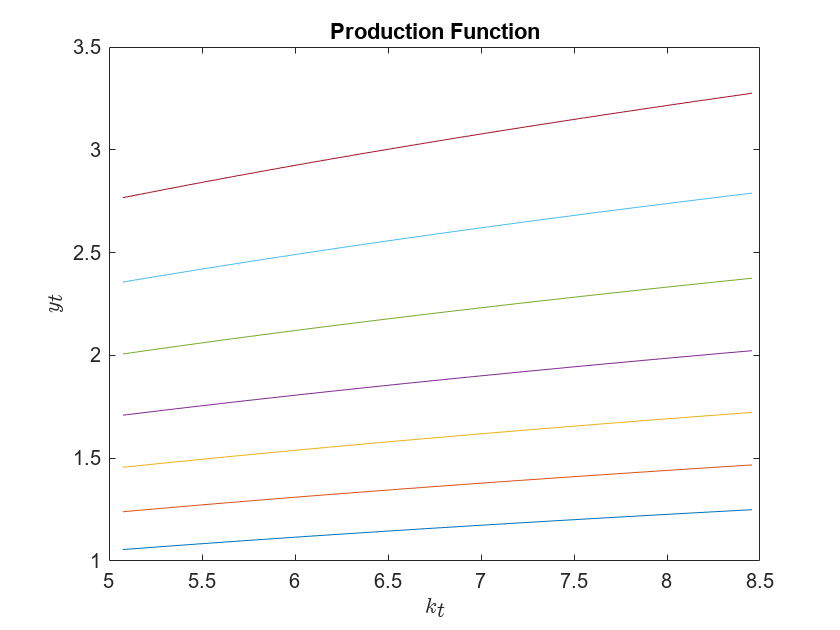

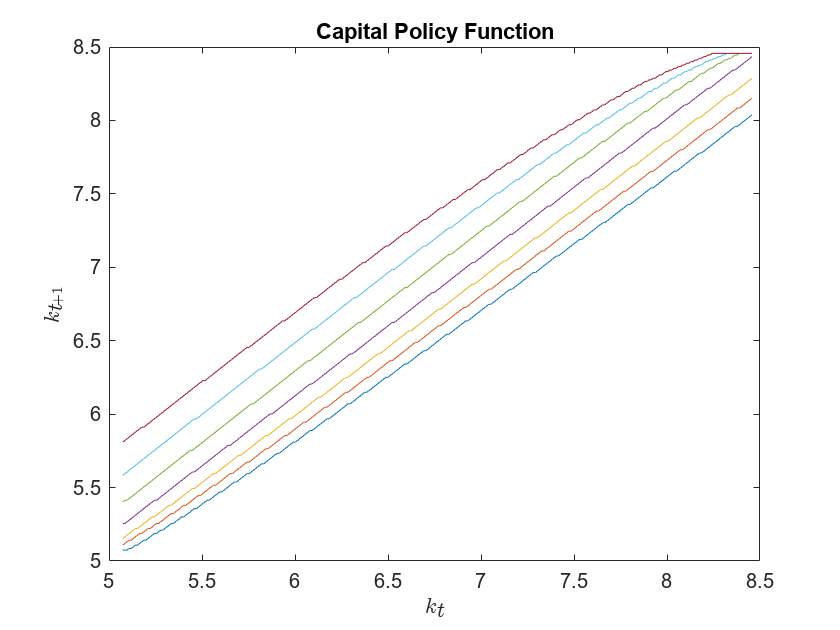

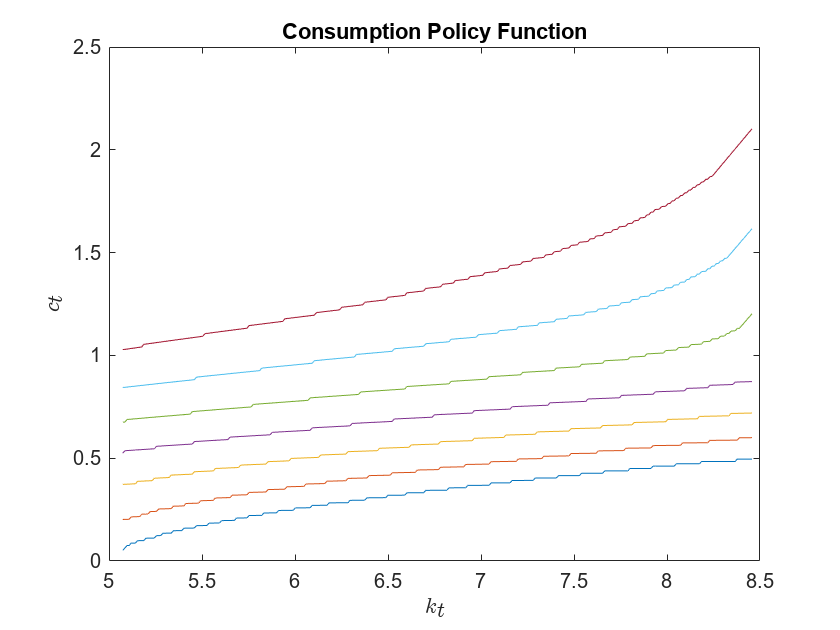

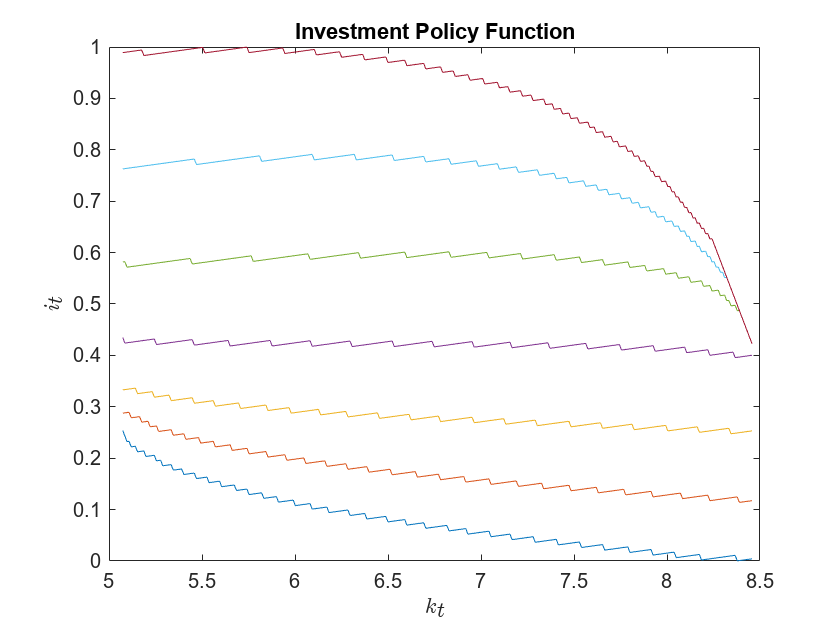

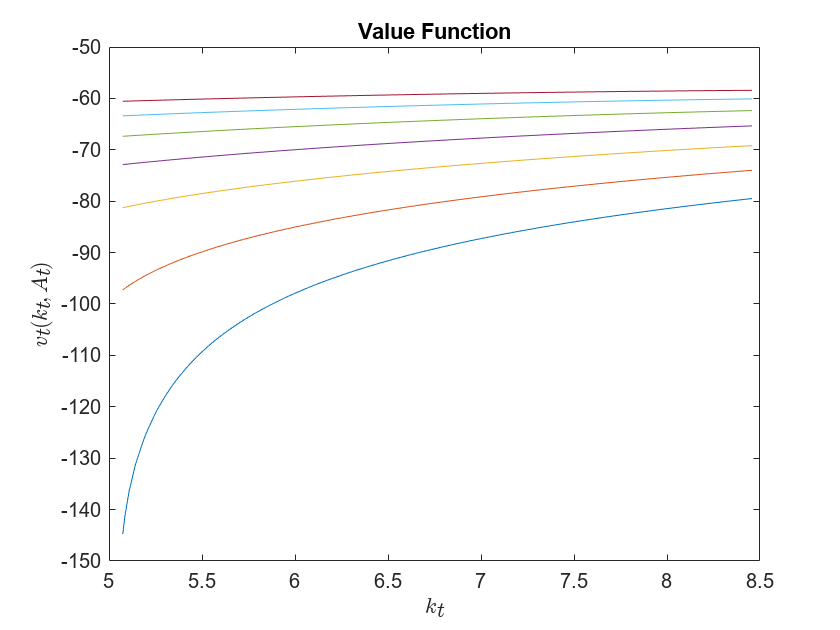

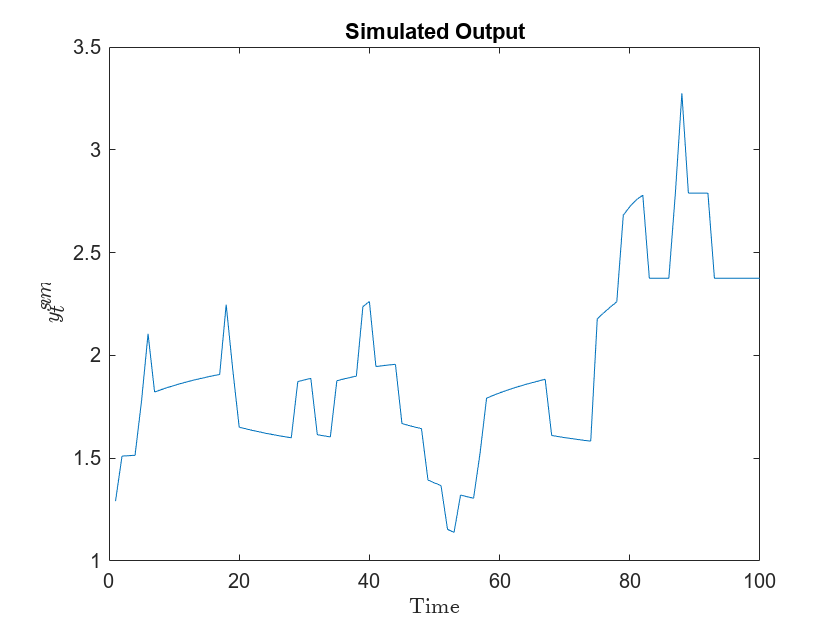

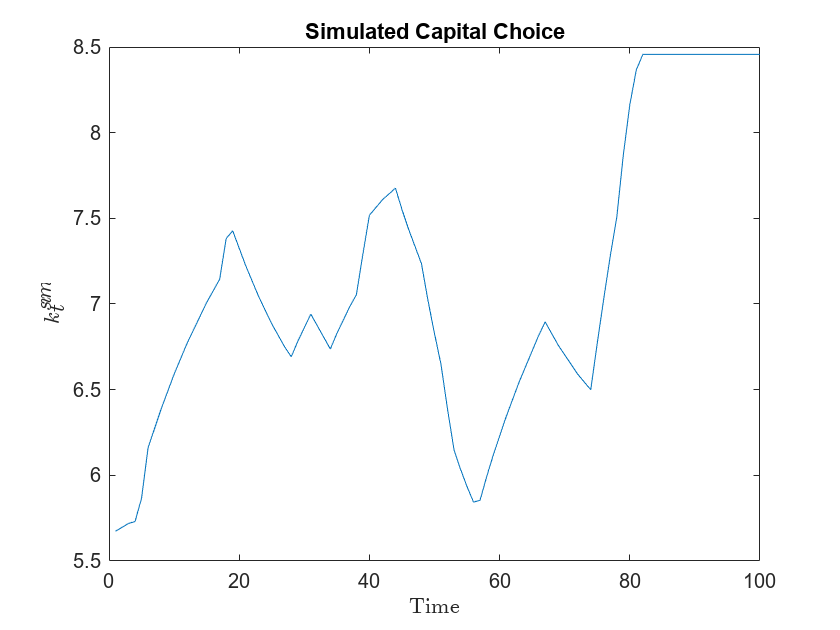

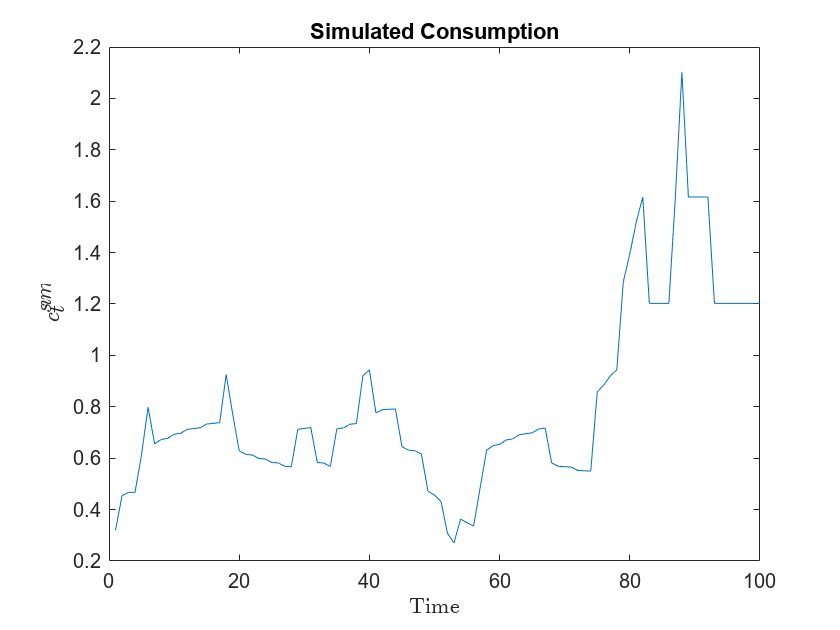

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.

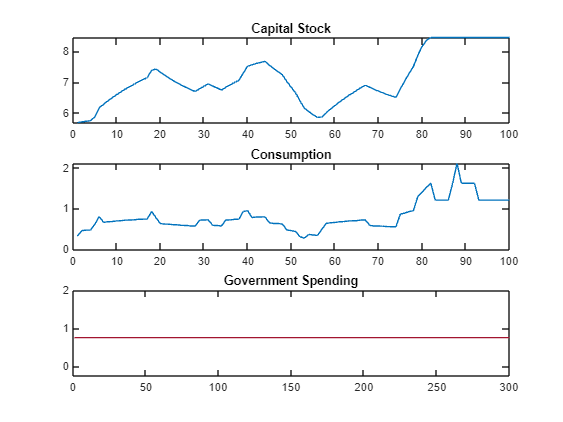

figure;
subplot(3,1,1); plot(sim.ksim); title('Capital Stock');
subplot(3,1,2); plot(sim.csim); title('Consumption');
subplot(3,1,3); plot(sol.g); title('Government Spending');

## Analysis.

To check the validity of the model, we compute statistics of interest and see how the data line up. In some cases, these are explicitly targeted by adjusting or estimating parameters that govern the behavior of the simulated data. In our case, we just set these exogenously from the literature, which in turn obtain these from data or estimation. The model differs from the literature so this model is off from the data, see Table 5.1 in Adda and Cooper.

% Compute the variables corresponding to data. The model assumes the data are detrended.
ysim = sim.ysim; % Output.
ksim = sim.ksim; % Capital Stock.
isim = sim.isim; % Investment.
csim = sim.csim; % Consumption.
gsim = sim.gsim; % Government.

% Std. Dev of variables relative to output.
cvar = sqrt(var(csim))/sqrt(var(ysim));
ivar = sqrt(var(isim))/sqrt(var(ysim));
gvar = sqrt(var(gsim))/sqrt(var(ysim));


fprintf('The Std. Dev of Consumption Relative to Output is: %0.4f',cvar)

The Std. Dev of Consumption Relative to Output is: 0.8310

fprintf('The Std. Dev of Investment Relative to Output is: %0.4f',ivar)

The Std. Dev of Investment Relative to Output is: 0.2887

fprintf('The Std. Dev of Government Relative to Output is: %0.4f',gvar)

The Std. Dev of Government Relative to Output is: 0.0000